# Curves defined implicitly by functions

Not every curve can be expressed in terms of an explicit function. Curves can also be expressed implicitly through relationships between variables. 

For example, the equation for a circle of radius 1, centered at the origin is $x^2 + y^2 -1 = 0$. The left-hand side of this equation can be thought of as a function of two variables, $f(x,y) = x^2 + y^2 -1$, and the set of points, $(x, y)$, where $f=0$ defines a curve, which we call the unit circle.

To evaluate functions of two variables in MATLAB, we'll use meshgrid.  Before you go on, you should [read about meshgrid in this article](https://www.mathworks.com/company/newsletters/articles/using-matlabs-meshgrid-command-and-array-operators-to-implement-one-and-two-variable-functions.html).

Here are the steps we'll follow to evaluate$f(x,y)$:

- We'll define **myfunc1** to take **x** and **y** as input variables and return **f(x, y)** as an output variable.

- We'll create a 1D matrix called x with a range of values along the x-axis, and a 1D matrix y with a range of values along the y-axis.

- We'll use meshgrid to create two 2D matrices, xgrid and ygrid.

- We'll use myfunc1 to evaluate f for all values in xgrid and ygrid.

As usual, we have to put all function definitions at the end, but here is a copy of myfunc1

**function res = myfunc1(x, y)**

**    res = x.^2 + y.^2 - 1;**

**end**

Notice that we have to use **.^**, which computes exponentiation elementwise.

Now we'll define **x** and **y**.

x = linspace(-5, 5, 500)

x =    -5.0000   -4.9800   -4.9599   -4.9399   -4.9198   -4.8998   -4.8798   -4.8597   -4.8397   -4.8196   -4.7996   -4.7796   -4.7595   -4.7395   -4.7194   -4.6994   -4.6794   -4.6593   -4.6393   -4.6192   -4.5992   -4.5792   -4.5591   -4.5391   -4.5190   -4.4990   -4.4790   -4.4589   -4.4389   -4.4188   -4.3988   -4.3788   -4.3587   -4.3387   -4.3186   -4.2986   -4.2786   -4.2585   -4.2385   -4.2184   -4.1984   -4.1784   -4.1583   -4.1383   -4.1182   -4.0982   -4.0782   -4.0581   -4.0381   -4.0180


y = x

y =    -5.0000   -4.9800   -4.9599   -4.9399   -4.9198   -4.8998   -4.8798   -4.8597   -4.8397   -4.8196   -4.7996   -4.7796   -4.7595   -4.7395   -4.7194   -4.6994   -4.6794   -4.6593   -4.6393   -4.6192   -4.5992   -4.5792   -4.5591   -4.5391   -4.5190   -4.4990   -4.4790   -4.4589   -4.4389   -4.4188   -4.3988   -4.3788   -4.3587   -4.3387   -4.3186   -4.2986   -4.2786   -4.2585   -4.2385   -4.2184   -4.1984   -4.1784   -4.1583   -4.1383   -4.1182   -4.0982   -4.0782   -4.0581   -4.0381   -4.0180


**meshgrid** is the first function we've seen that returns two output variables.  Here's how we use it.

[xgrid, ygrid] = meshgrid(x, y)

xgrid =    -5.0000   -4.9800   -4.9599   -4.9399   -4.9198   -4.8998   -4.8798   -4.8597   -4.8397   -4.8196   -4.7996   -4.7796   -4.7595   -4.7395   -4.7194   -4.6994   -4.6794   -4.6593   -4.6393   -4.6192   -4.5992   -4.5792   -4.5591   -4.5391   -4.5190   -4.4990   -4.4790   -4.4589   -4.4389   -4.4188   -4.3988   -4.3788   -4.3587   -4.3387   -4.3186   -4.2986   -4.2786   -4.2585   -4.2385   -4.2184   -4.1984   -4.1784   -4.1583   -4.1383   -4.1182   -4.0982   -4.0782   -4.0581   -4.0381   -4.0180
   -5.0000   -4.9800   -4.9599   -4.9399   -4.9198   -4.8998   -4.8798   -4.8597   -4.8397   -4.8196   -4.7996   -4.7796   -4.7595   -4.7395   -4.7194   -4.6994   -4.6794   -4.6593   -4.6393   -4.6192   -4.5992   -4.5792   -4.5591   -4.5391   -4.5190   -4.4990   -4.4790   -4.4589   -4.4389   -4.4188   -4.3988   -4.3788   -4.3587   -4.3387   -4.3186   -4.2986   -4.2786   -4.2585   -4.2385   -4.2184   -4.1984   -4.1784   -4.1583   -4.1383   -4.1182   -4.0982   -4.0782   -4.0581   -4.0381 

ygrid =    -5.0000   -5.0000   -5.0000   -5.0000   -5.0000   -5.0000   -5.0000   -5.0000   -5.0000   -5.0000   -5.0000   -5.0000   -5.0000   -5.0000   -5.0000   -5.0000   -5.0000   -5.0000   -5.0000   -5.0000   -5.0000   -5.0000   -5.0000   -5.0000   -5.0000   -5.0000   -5.0000   -5.0000   -5.0000   -5.0000   -5.0000   -5.0000   -5.0000   -5.0000   -5.0000   -5.0000   -5.0000   -5.0000   -5.0000   -5.0000   -5.0000   -5.0000   -5.0000   -5.0000   -5.0000   -5.0000   -5.0000   -5.0000   -5.0000   -5.0000
   -4.9800   -4.9800   -4.9800   -4.9800   -4.9800   -4.9800   -4.9800   -4.9800   -4.9800   -4.9800   -4.9800   -4.9800   -4.9800   -4.9800   -4.9800   -4.9800   -4.9800   -4.9800   -4.9800   -4.9800   -4.9800   -4.9800   -4.9800   -4.9800   -4.9800   -4.9800   -4.9800   -4.9800   -4.9800   -4.9800   -4.9800   -4.9800   -4.9800   -4.9800   -4.9800   -4.9800   -4.9800   -4.9800   -4.9800   -4.9800   -4.9800   -4.9800   -4.9800   -4.9800   -4.9800   -4.9800   -4.9800   -4.9800   -4.9800 

The first output variable gets assigned to **xgrid**, the second gets assigned to **ygrid**.

Now we can evaluate **myfunc1**

z = myfunc1(xgrid, ygrid)

z =    49.0000   48.8000   48.6008   48.4024   48.2048   48.0080   47.8121   47.6169   47.4225   47.2289   47.0362   46.8442   46.6530   46.4627   46.2731   46.0843   45.8964   45.7093   45.5229   45.3374   45.1526   44.9687   44.7856   44.6032   44.4217   44.2410   44.0611   43.8819   43.7036   43.5261   43.3494   43.1735   42.9984   42.8241   42.6506   42.4779   42.3061   42.1350   41.9647   41.7952   41.6265   41.4587   41.2916   41.1253   40.9599   40.7952   40.6314   40.4683   40.3061   40.1446
   48.8000   48.6000   48.4008   48.2024   48.0048   47.8080   47.6121   47.4169   47.2225   47.0289   46.8362   46.6442   46.4530   46.2627   46.0731   45.8843   45.6964   45.5093   45.3229   45.1374   44.9526   44.7687   44.5856   44.4032   44.2217   44.0410   43.8611   43.6819   43.5036   43.3261   43.1494   42.9735   42.7984   42.6241   42.4506   42.2779   42.1061   41.9350   41.7647   41.5952   41.4265   41.2587   41.0916   40.9253   40.7599   40.5952   40.4314   40.2683   40.1061   39

## Finding zeros

Now we'd like to find the places where $f(x,y)$is 0.  The MATLAB function contour generates a contour plot, which shows the locations where the function has particular values.

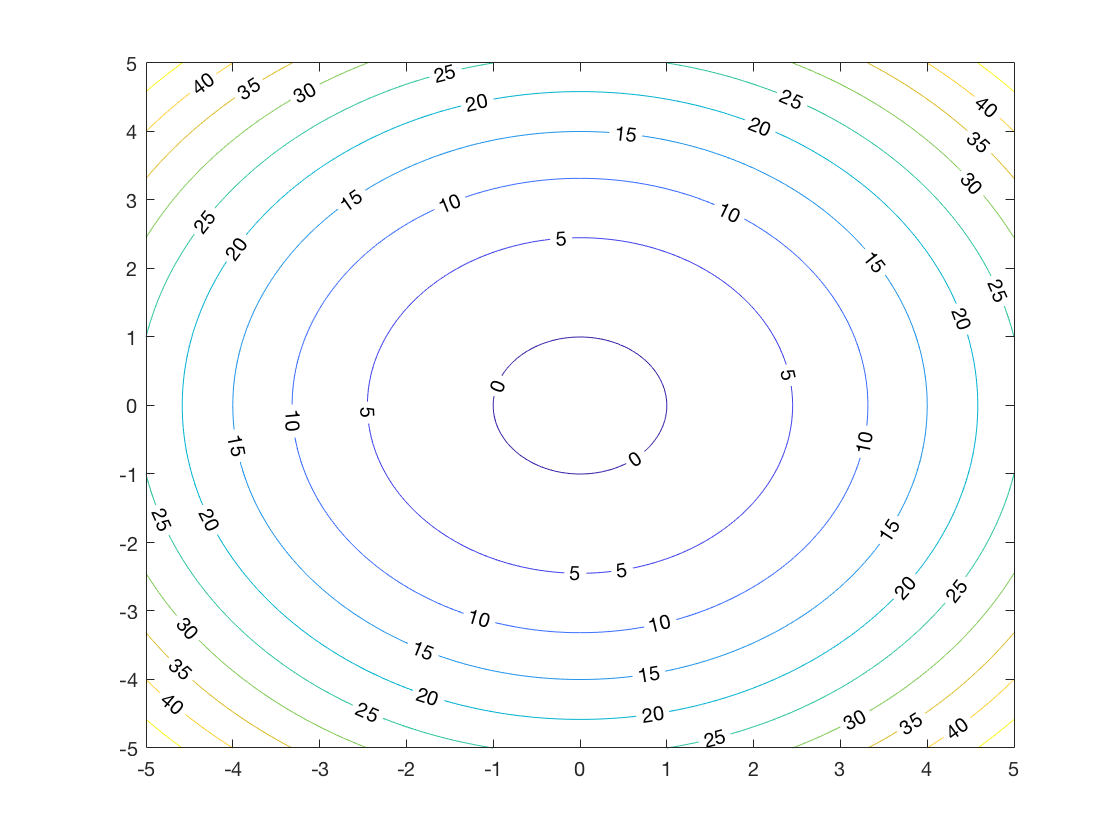

contour(xgrid,ygrid,z,'ShowText','on');

In this example, 0 is one of the values contour chooses automatically, but we can also specify the values we want.

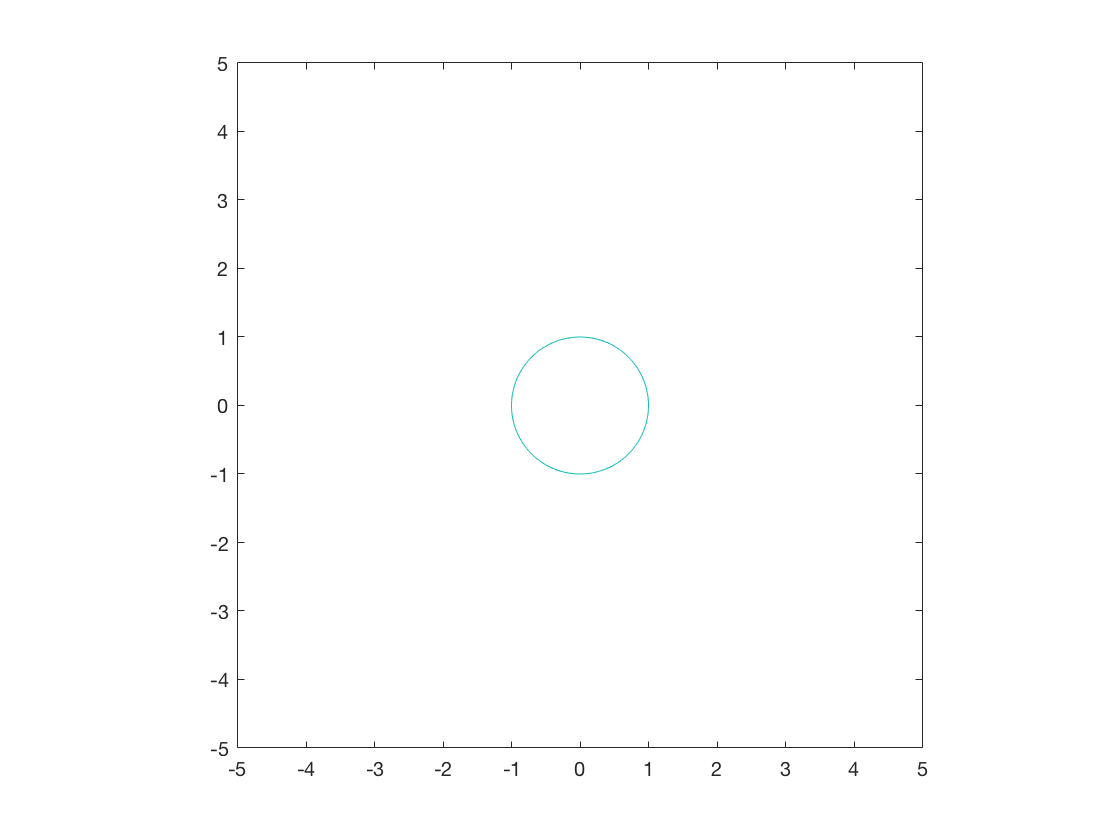

v = [0,0];
contour(xgrid,ygrid,z,v);
axis('equal')

By specifying that the axes should be equal, we make it clearer that the results form a circle.

We can use **contourc** to compute the locations where $f(x,y)$is 0 and return them in an array.  The result, C, is a ContourArray, which stores the results, in a matrix, in a weird format.  To unpack the values in this matrix, we'll use [matrix indexing, which you should read about in this article](https://www.mathworks.com/company/newsletters/articles/matrix-indexing-in-matlab.html).

C = contourc(x,y,z,v)

C =          0   -0.9920   -0.9915   -0.9886   -0.9853   -0.9817   -0.9776   -0.9731   -0.9719   -0.9681   -0.9627   -0.9568   -0.9519   -0.9505   -0.9437   -0.9364   -0.9319   -0.9287   -0.9204   -0.9118   -0.9117   -0.9024   -0.8926   -0.8918   -0.8821   -0.8717   -0.8712   -0.8595   -0.8517   -0.8473   -0.8344   -0.8317   -0.8208   -0.8116   -0.8065   -0.7916   -0.7915   -0.7755   -0.7715   -0.7588   -0.7515   -0.7411   -0.7315   -0.7224   -0.7114   -0.7027   -0.6914   -0.6818   -0.6713   -0.6597
  401.0000    0.1261    0.1303    0.1503    0.1703    0.1904    0.2104    0.2305    0.2351    0.2505    0.2705    0.2906    0.3063    0.3106    0.3307    0.3507    0.3627    0.3707    0.3908    0.4106    0.4108    0.4309    0.4509    0.4524    0.4709    0.4899    0.4910    0.5110    0.5239    0.5311    0.5511    0.5552    0.5711    0.5841    0.5912    0.6111    0.6112    0.6313    0.6361    0.6513    0.6597    0.6713    0.6818    0.6914    0.7027    0.7114    0.7224    0.7315    0.7411    0

level = C(1,1)

level = 0

numxy = C(2,1)

numxy = 401

xzero = C(1,2:end)

xzero =    -0.9920   -0.9915   -0.9886   -0.9853   -0.9817   -0.9776   -0.9731   -0.9719   -0.9681   -0.9627   -0.9568   -0.9519   -0.9505   -0.9437   -0.9364   -0.9319   -0.9287   -0.9204   -0.9118   -0.9117   -0.9024   -0.8926   -0.8918   -0.8821   -0.8717   -0.8712   -0.8595   -0.8517   -0.8473   -0.8344   -0.8317   -0.8208   -0.8116   -0.8065   -0.7916   -0.7915   -0.7755   -0.7715   -0.7588   -0.7515   -0.7411   -0.7315   -0.7224   -0.7114   -0.7027   -0.6914   -0.6818   -0.6713   -0.6597   -0.6513


yzero = C(2,2:end)

yzero =     0.1261    0.1303    0.1503    0.1703    0.1904    0.2104    0.2305    0.2351    0.2505    0.2705    0.2906    0.3063    0.3106    0.3307    0.3507    0.3627    0.3707    0.3908    0.4106    0.4108    0.4309    0.4509    0.4524    0.4709    0.4899    0.4910    0.5110    0.5239    0.5311    0.5511    0.5552    0.5711    0.5841    0.5912    0.6111    0.6112    0.6313    0.6361    0.6513    0.6597    0.6713    0.6818    0.6914    0.7027    0.7114    0.7224    0.7315    0.7411    0.7515    0.7588


Now xzero and yzero contain corresponding values of x and y where $f(x,y)$is 0, and we can plot them.

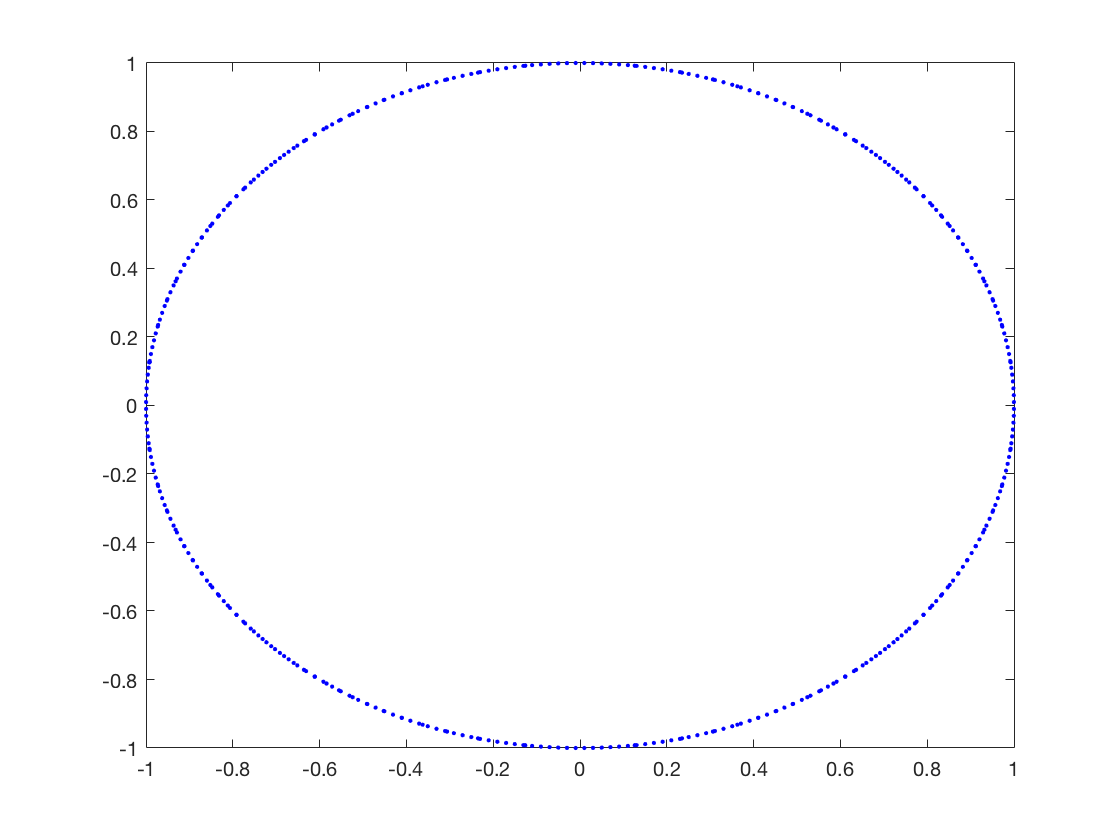

plot(xzero, yzero,'b.')

## Generalizing

There is no end to the functions of two variables that you can define. There is, however, a set of functions that show up again and again, and these are the quadratic functions of two variables. The general form (containing all possible quadratic, linear and constant terms) is


$$f(x,y) = A x^2+B x y + C y^2+D x + E y + F$$


where A,B,C,D,E,and F are arbitrary parameters, some of which may be zero. The curves defined by $f=0$ are called conic sections, and represent the intersection of a double cone and a plane. The non-degenerate cases include circles, parabolas, ellipses, and hyperbolas.

**Exercise 1**: Use **contour** to visualize solutions to the equation 


$$\frac{x^2}{a^2} + \frac{y^2}{b^2} - 1 = 0$$


for different values of **a** and **b**. What kind of curve do you get?  What features of the curve do $a$ and $b$ control?  Hint: Write a function called **myfunc2** that takes **x**, **y**, **a**, and **b** as input variables.  Use a for loop to plot contours for a range of values for **a**, with **b** held constant.

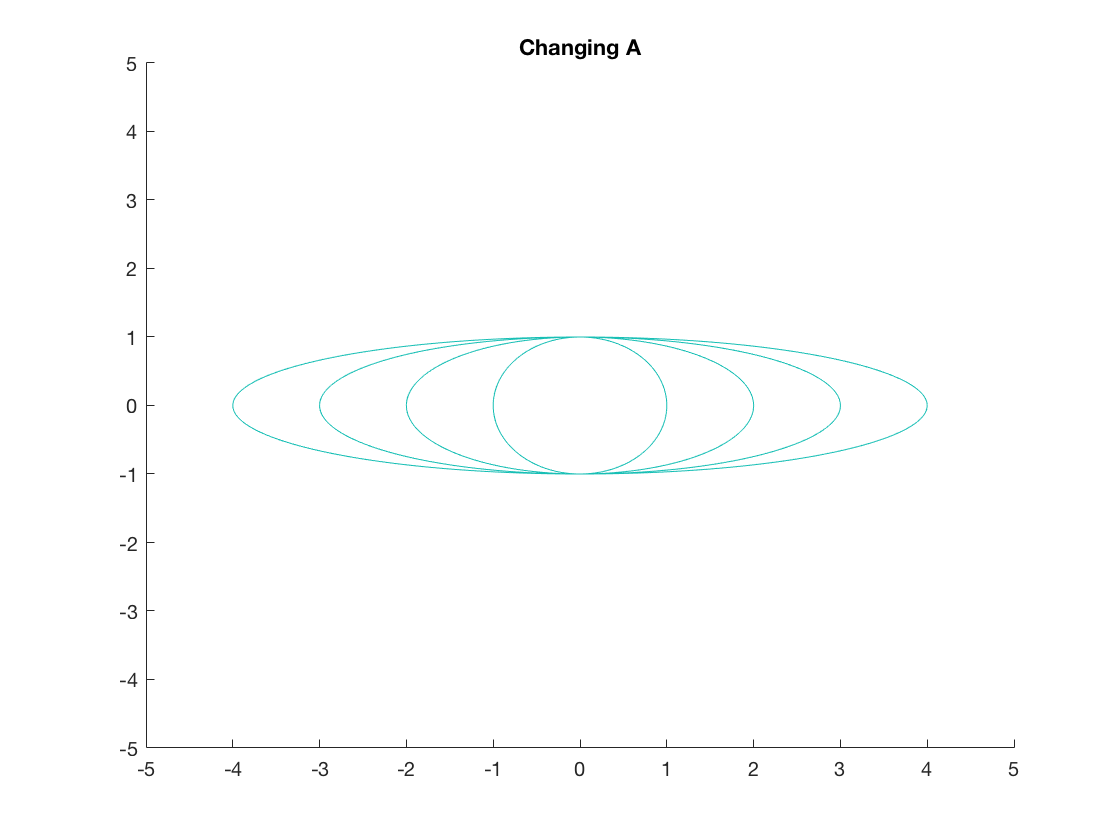

newplot; hold on
title('Changing A')

for a = 4:-1:1
    contour(xgrid, ygrid, myfunc2(xgrid, ygrid, a, 1), [0,0])
end

hold off

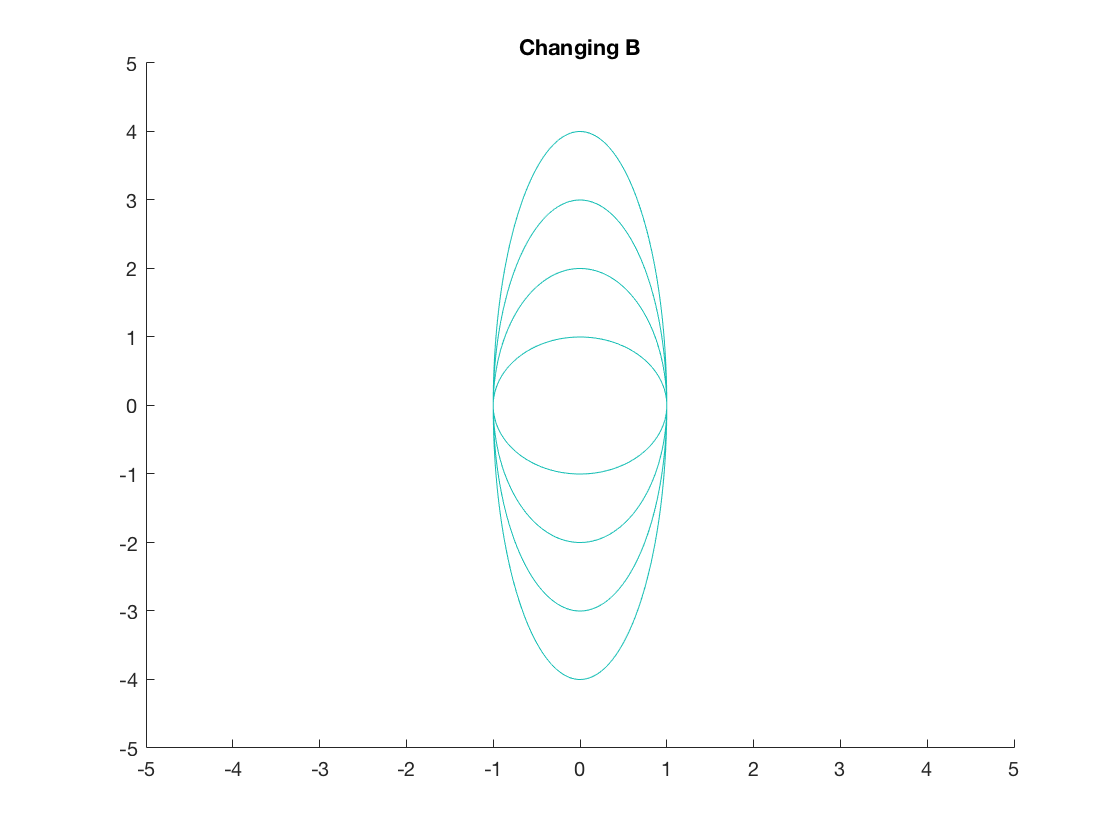

newplot; hold on
title('Changing B')

for b = 4:-1:1
    contour(xgrid, ygrid, myfunc2(xgrid, ygrid, 1, b), [0,0])
end

hold off

    **Bogdan:** *The curve is that of an ellipse. a and b each control one of the focal points.*

Use **contour** to visualize solutions to the equation 


$$\frac{x^2}{a^2} - \frac{y^2}{b^2} - 1 = 0$$
 

for different values of a and b. What kind of curve do you get?  What features of the curve do $a$ and $b$ control?

**Exercise 2**: Do some internet research to find out under what conditions the solutions of $f
$define an ellipse, a parabola, a hyperbola, or a circle. Visualize solutions for each of the conditions and confirm that they are correct.

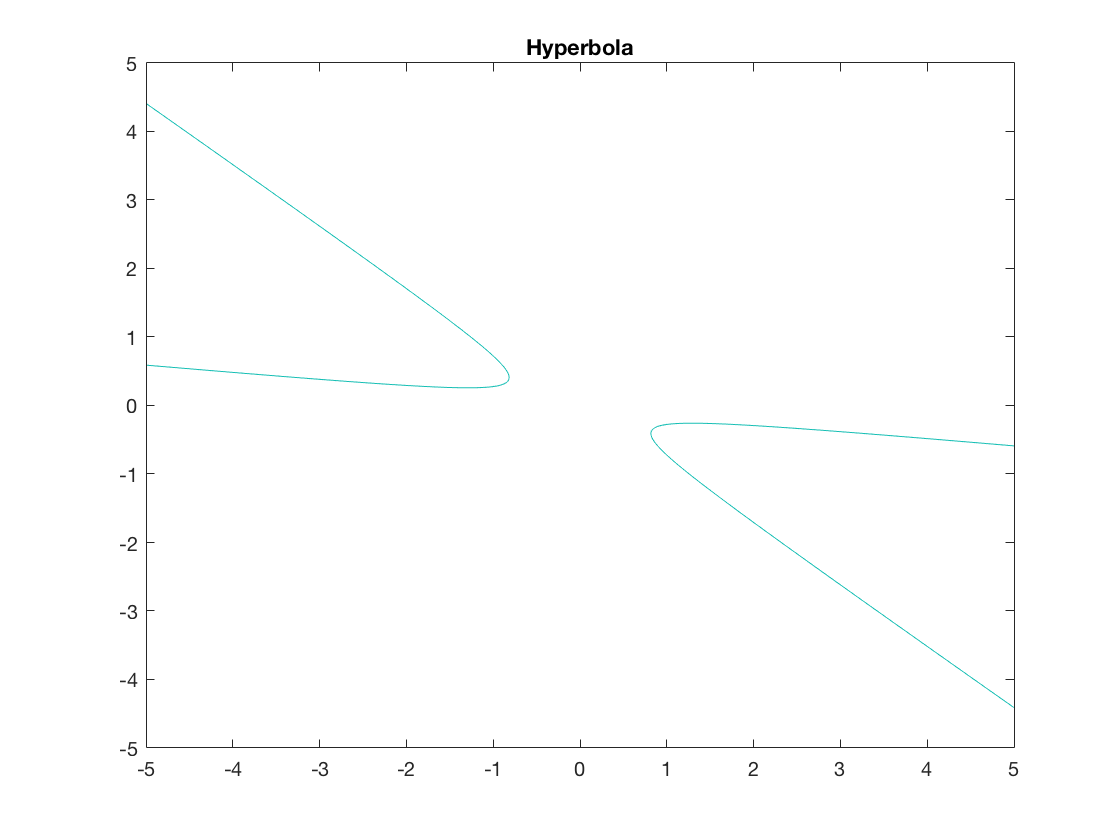

% Hyperbola

a=1; b=10; c=10; d=0; e=0; f=1;
contour(xgrid, ygrid, myfunc3(xgrid, ygrid, a, b, c, d, e, f), [0,0])
title('Hyperbola')


isHyperbola = b^2 - 4*a*c > 0

isHyperbola = logical
   1


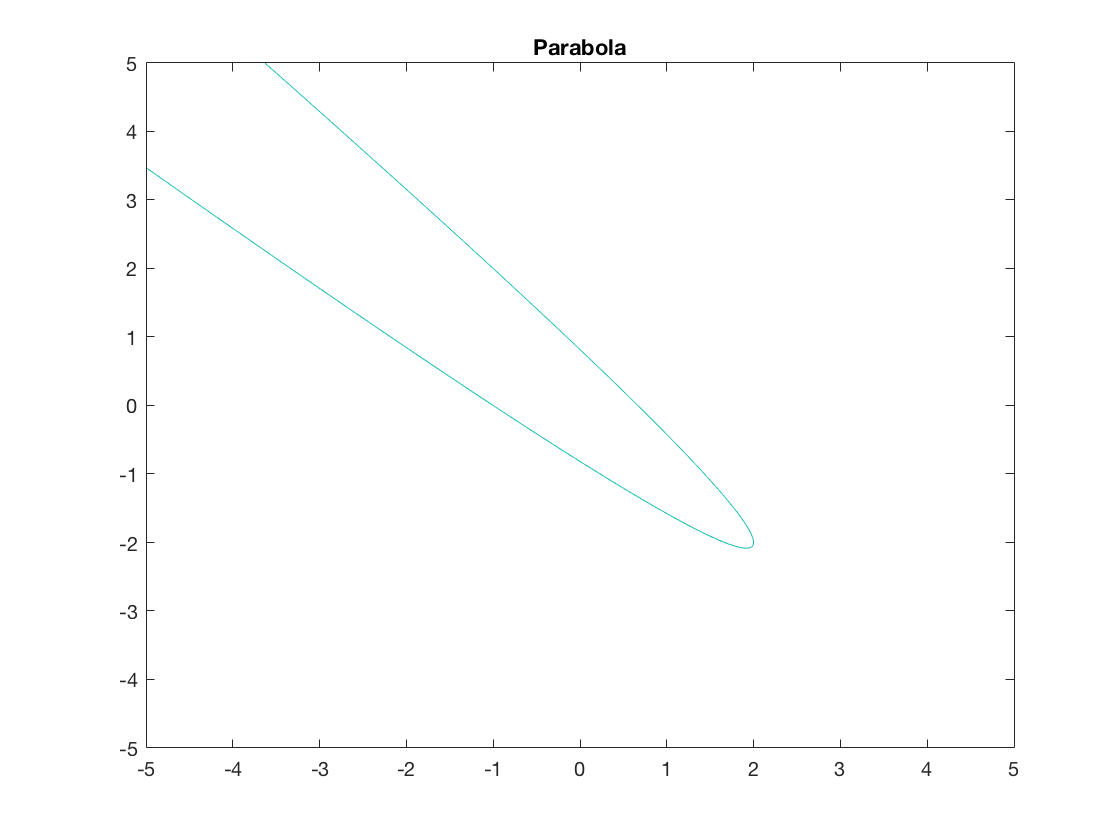

% Parabola

a=3; b=6; c=3; d=1; e=0; f=-2;
contour(xgrid, ygrid, myfunc3(xgrid, ygrid, a, b, c, d, e, f), [0,0])
title('Parabola')


isParabola = b^2 - 4*a*c == 0

isParabola = logical
   1


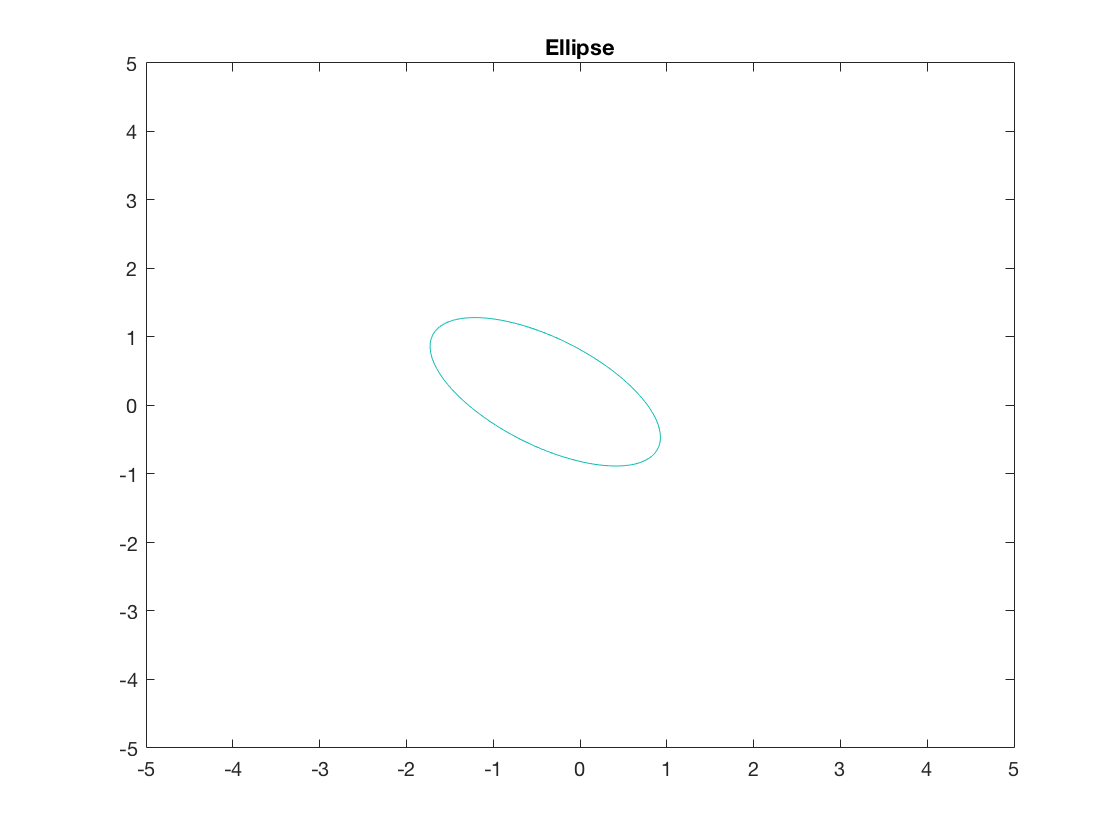

% Ellipse

a=2; b=3; c=3; d=1; e=0; f=-2;
contour(xgrid, ygrid, myfunc3(xgrid, ygrid, a, b, c, d, e, f), [0,0])
title('Ellipse')


isEllipse = b^2 - 4*a*c < 0

isEllipse = logical
   1


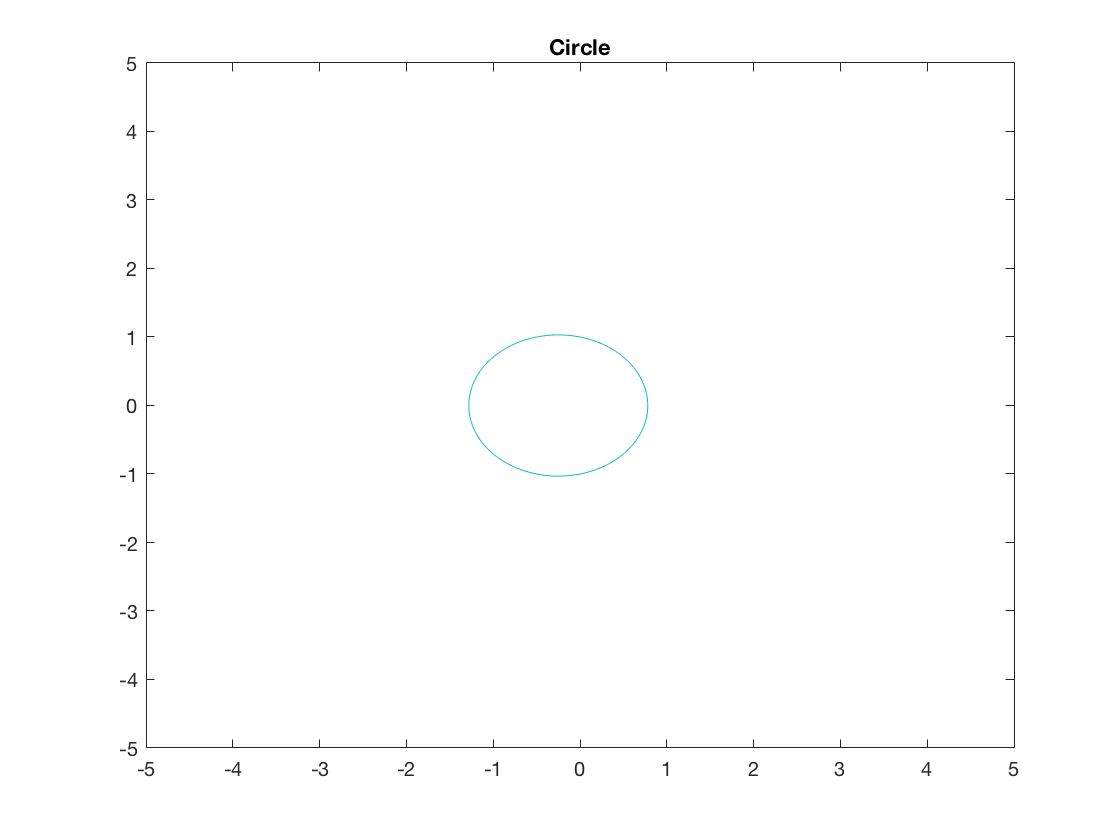

% Circle

a=2; b=0; c=2; d=1; e=0; f=-2;
contour(xgrid, ygrid, myfunc3(xgrid, ygrid, a, b, c, d, e, f), [0,0])
title('Circle')


isCircle = (b^2 - 4*a*c < 0) && (a==c) && (b==0)

isCircle = logical
   1


## Function definitions

function res = myfunc1(x,y)
    % myfunc1   Computes f(x, y) = x^2 + y^2 -1
    res = x.^2 + y.^2 - 1;
end

function res = myfunc2(x, y, a, b)
    res = x.^2/a.^2 + y.^2/b.^2 - 1;
end

function res = myfunc3(x,y,a,b,c,d,e,f)
    res = a.*x.^2 + b.*x.*y + c.*y.^2 + d.*x + e.*y + f;
end
